**Giordano Dylan - Martelet Curtis                            L3 EEA_Gr TP1**

# Rapport TP10: Composants de Puissance

## 2/ Caractérisation statique d'une diode

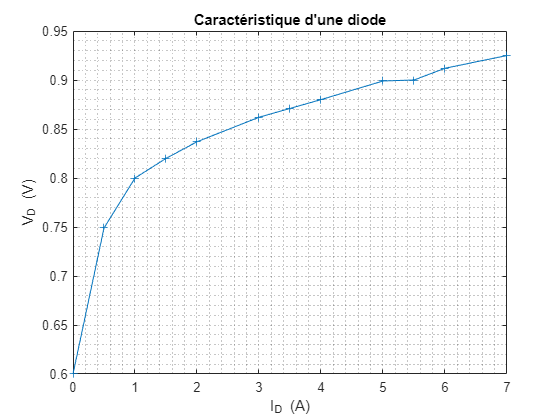

id=[0 0.5 1 1.5 2 3 3.5 4 5 5.5 6 7];
Vd=[0.6 0.749 0.8 0.82 0.837 0.862 0.871 0.88 0.899 0.9 0.912 0.925];
plot(id,Vd,'+-')
title("Caractéristique d'une diode")
xlabel('I_D (A)');ylabel('V_D (V)')
grid minor

La caractéristique d'une diode de pont redresseur est de la forme exponentielle, ce qui est normal.

## 3/ Mesure des pertes par une méthode d'opposition

### 2. Mesure

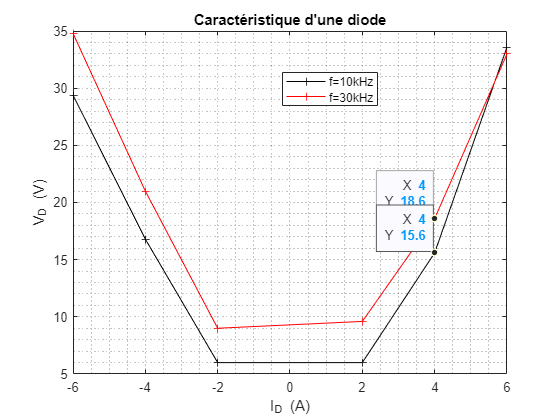

Is=[-6 -4 -2 2 4 6];
Pe10=[29.4 16.8 6 6 15.6 33.6];%%Pour f=10kHz
Pe30=[34.8 21 9 9.6 18.6 33]; %%Pour f=30kHz
plot(Is,Pe10,'k+-',Is,Pe30,'r+-')
title("Caractéristique d'une diode")
xlabel('I_D (A)');ylabel('V_D (V)')
legend("f=10kHz","f=30kHz","Position",[0.5044,0.74738,0.17143,0.082143])
ax = gca;
chart = ax.Children(1);
datatip(chart,4,18.6);
ax2 = gca;
chart2 = ax2.Children(2);
datatip(chart2,4,15.6);
grid minor

dt = findobj(gca,"DataIndex",5);
set(dt,"Location","northwest");

### 3. Extraction des pertes par commutation et des pertes par conductions.

A une fréquence de 10kHz, on relève une tension $V_D =15\ldotp 6V$ ; à f=30kHz, la tension$V_D =18\ldotp 6V$.

On suppose que les pertes totales sont l'addition des pertes due aux commutations et à la conduction. En prenant la tension à deux fréquences différentes, on aura donc des pertes dues aux commutations différentes, mais les pertes par conductions seront constantes. On peut donc soustraires les deux tensions et trouver la perte provoquée par la conduction seule.

$\textrm{Perte}=V_{\textrm{D30}} -V_{\textrm{D10}} =18\ldotp 6-15\ldotp 6=3$. On en conclut que les pertes sont égales à 3.

### 4. Prédétermination des rendements d'un hacheur.

Ue = [60;60;60;60;60;60];Perte = [3;3;3;3;3;3];
Us = [50;20;20;20;-20;-50];
Is = [6;6;2;-6;-6;-6];


Ps = Us.*Is;
% Rendement:
Rendement = abs(Ps)./(abs(Ps)+Perte);
table(Ue,Perte,Us,Is,Ps,Rendement)

ans = 6×6 table
    Ue    Perte    Us     Is     Ps     Rendement
    __    _____    ___    __    ____    _________
    60      3       50     6     300      0.9901 
    60      3       20     6     120     0.97561 
    60      3       20     2      40     0.93023 
    60      3       20    -6    -120     0.97561 
    60      3      -20    -6     120     0.97561 
    60      3      -50    -6     300      0.9901 

En utilisant l'équation pour trouver le rendement: $\eta =\frac{\left|P_S \right|}{\left|P_S \right|+\mathrm{Perte}}$, on observe que le rendement reste constant.